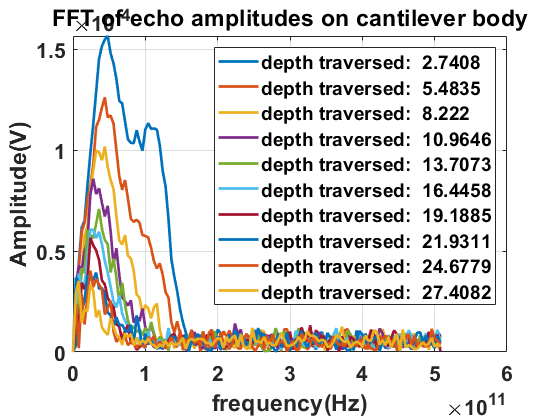

% clear all

echos_struct = load("10echoes_for_attenuation_newconfig_pd2.mat","echos");
echos_height = load("10echoes_for_attenuation_heights_newconfig_pd2.mat","tip_height");
echos = echos_struct.echos;
heights = echos_height.tip_height;
 
plotflag = 1;
[S_fft_sig] = take_fft(echos,heights,plotflag);

noise_range = [120e9 500e9]

noise_range = 	1.0e+11 *

    1.2000    5.0000


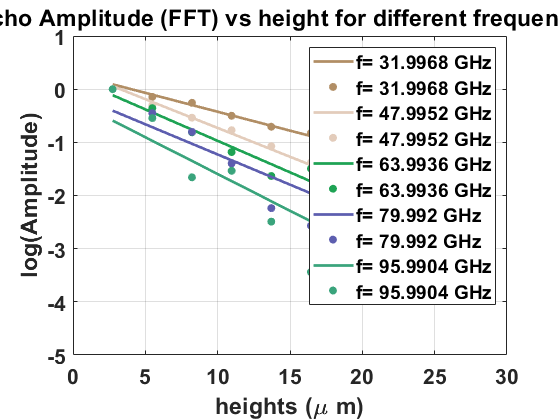

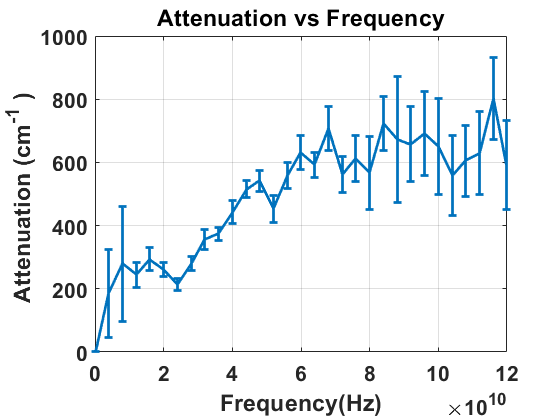

for i=1:numel(S_fft_sig)
    
    [noise_window,se,S_fft_sig_main{i},S_fft_sig_main_ver_noise] = standard_error(S_fft_sig{i},noise_range);
    
end

freq_range = S_fft_sig_main{1}(:,1);
plotidx = [9 13 17 21 25 29];

[alpha,alpha_se,Sig_Amp_log,Sig_Amp_regression,lin_mdl] = ...
    calculate_attenuation_from_depth(S_fft_sig_main,heights,freq_range,plotidx,0);

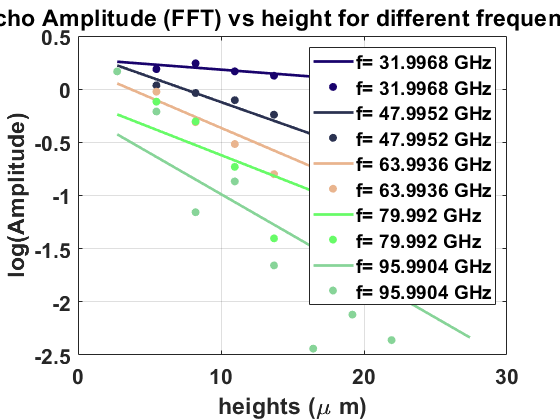

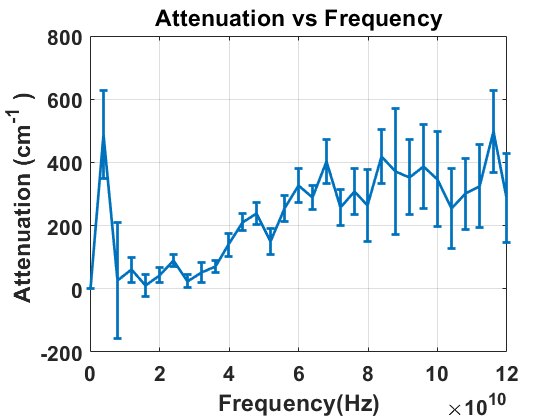

[alpha_r,alpha_se_r,Sig_Amp_log_r,Sig_Amp_regression_r,lin_mdl] = ...
    calculate_attenuation_from_depth(S_fft_sig_main,heights,freq_range,plotidx,0.08); % with strong adhesion

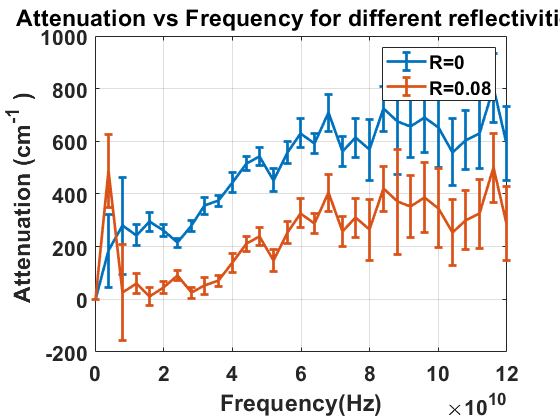


figure
    errorbar(freq_range,abs(10000*alpha),10000*alpha_se,"LineWidth",2,"MarkerSize",1)
    hold on
    errorbar(freq_range,abs(10000*alpha_r),10000*alpha_se_r,"LineWidth",2,"MarkerSize",1)
    legend(["R=0" "R=0.08"])
    set(gca,'FontSize',16,'FontWeight','bold')
    xlabel("Frequency(Hz)")
    ylabel("Attenuation (cm^{-1} ) ")
    title("Attenuation vs Frequency for different reflectivities")
    grid on

## Predicting echoes at a given height

height = 11.4;
Amp_height = S_fft_sig{1}(1:size(alpha_v_f_polyfit,1),2).*exp(-alpha_v_f_polyfit*(2*(heights(1)-height)));

% S_fft_sig_main{5} = S_


function [S_fft_sig] = take_fft(echos,heights,plotflag)    
    
    for i=1:numel(echos)
        
        echo_time_sig = echos{i}(:,1);
        echo_sig = echos{i}(:,2);
        
        pad_length = 2^nextpow2(length(echo_time_sig));
    
        f_sig = 0:1/(pad_length*(echo_time_sig(2)-echo_time_sig(1)))...
            :(1/(echo_time_sig(2)-echo_time_sig(1)))-1/(pad_length*(echo_time_sig(2)-echo_time_sig(1)));
        
        S_sig = fft(echo_sig,pad_length);
        S_fft_sig{i} = [f_sig(1:pad_length/2)' S_sig(1:pad_length/2)]; 
        
        if plotflag==1
            plot(f_sig(1:pad_length/2),abs(S_sig(1:pad_length/2)),"Linewidth",2)
            xlabel("frequency(Hz)")
            ylabel("Amplitude(V)")            
            set(gca,'FontSize',16,'FontWeight','bold')
            title("FFT of echo amplitudes on cantilever body")
            legend_str(i) = strjoin(["depth traversed: " num2str(heights(i))]);
            grid on
            hold on
        end    
    end
    legend(legend_str)
    hold off  

end

function [noise_window, se,data_main,data_over_noise] = standard_error(data,window)%,del_t,time_window_size)    
%     first_echo_time = 0.5985e-9;
%     second_echo_time = 2*first_echo_time;
%     third_echo_time = 3*first_echo_time;
%     del_t = (first_echo_time+second_echo_time)/2;
    [~,data_x_window_idx1] = min(abs(data(:,1)-window(1)));
    [~,data_x_window_idx2] = min(abs(data(:,1)-window(2)));
    
    noise_window = data(data_x_window_idx1:data_x_window_idx2,:);
    
    se = std(noise_window(:,2));
    data_over_noise = data(data(:,2)>1.2*se,:); %Extracting the signal over the noise level
    data_main = data(1:data_x_window_idx1,:);
    
    %*size(first_echo_sig,2);
%     se = max(noise_window(2,:)) - min(noise_window(2,:));
    
    
end

function[alpha,freq_range,alpha_v_f,alpha_v_f_val] = calculate_attenuation(S_fft_sig_main,heights,plotflag)
    
    % Calculating attenuation factor from all frequency points at all
    % heights
    % Collecting attenuation from each pair of spectrum in a  cell array
    % where each element represents attenuation from one height
    count = 1;
    n = numel(S_fft_sig_main);    
    alpha_v_f = [];
    for i=1:n        
        for j=i+1:n  
            freq_range{i}(:,j-i) = S_fft_sig_main{i}(:,1);
            alpha{i}(:,j-i) = -log(abs(S_fft_sig_main{j}(:,2))./abs(S_fft_sig_main{i}(:,2)))./...
                (2*(heights(j)-heights(i))); 
            count = count+1;
            
            alpha_v_f = cat(2,alpha_v_f,alpha{i}(:,j-i));
%             alpha_v_f_poly = polyfit(alpha_v_f(:,1),alpha_v_f(:,2),2);
            %plotting attenuation points with frequency 
            
             if plotflag==1
                scatter(freq_range{i}(:,j-i),alpha{i}(:,j-i),"MarkerEdgeAlpha",2)
                xlabel("frequency(Hz)")
                ylabel("\alpha")            
                set(gca,'FontSize',16,'FontWeight','bold')
                title("Attenuation factor vs frequency between echoes at different depths ")
                set(gca,'FontSize',16,'FontWeight','bold')
                legend_str(count) = strjoin(["\Deltah: " num2str(i) "-" num2str(j)]);
                grid on
                hold on
            end    

        end       
        
    end  
    legend(legend_str)
    
    alpha_v_f_mean = mean(alpha_v_f,2);
    alpha_v_f_sd = std(alpha_v_f,0,2);
    alpha_v_f_poly_coeff_ord1 = polyfit(freq_range{1}(:,1),alpha_v_f(:,2),1);
    alpha_v_f_val = polyval(alpha_v_f_poly_coeff_ord1,freq_range{1}(:,1));
    
    plot(freq_range{1}(:,1),alpha_v_f_val,"LineWidth",2)
    
     
    hold off

end

function[alpha,alpha_se,Sig_Amp_log,Sig_amp_log_regression,lin_mdl] = ...
    calculate_attenuation_from_depth(S_fft_sig_main,heights,freq_range,plotidx,reflectivity_alsi)
    
    % Calculating attenuation factor from all frequency points at all
    % heights
    % Collecting attenuation from each pair of spectrum in a  cell array
    % where each element represents attenuation from one height
    count = 1;
    n = numel(S_fft_sig_main);    
    alpha_v_f = [];
%     reflectivity_alsi = 0.08;
    
    for i=2:length(S_fft_sig_main{1}(:,1))
        
        for j=1:numel(S_fft_sig_main)
            Sig_Amp_log(i,j) = log(abs(S_fft_sig_main{j}(i,2))/abs(S_fft_sig_main{1}(i,2)))-(2*j*log(1-reflectivity_alsi));
        end
        
        % Fitting linear model and extracting the attenuation coefficient 
        lin_mdl = fitlm(2*(heights-heights(1)), Sig_Amp_log(i,:));
        
        Sig_amp_log_regression(i,:) = (lin_mdl.Fitted)';        
        alpha(i) = table2array(lin_mdl.Coefficients(2,1));
        alpha_se(i) = table2array(lin_mdl.Coefficients(2,2));
        color = rand(1,3); 
        
        if plotidx(count) == i && count < length(plotidx)
            
            l(2*count-1) = strjoin(["f=" num2str(freq_range(plotidx(count))/1e9),"GHz"]);
            l(2*count) = strjoin(["f=" num2str(freq_range(plotidx(count))/1e9),"GHz"]);
            
            plot(heights,Sig_amp_log_regression(i,:),'LineWidth',2,"Color",color)
            grid on
            hold on
            scatter(heights,Sig_Amp_log(i,:),[],color,"filled","DisplayName",l(count))
            set(gca,'FontSize',16,'FontWeight','bold')
            xlabel("heights (\mu m)")
            ylabel("log(Amplitude)")
            title("Echo Amplitude (FFT) vs height for different frequencies")
            hold on
%             legend("off")
            count = count +1;
%             legend(legend_str)

            
        end     
       
        
    end 
    legend(l)  
    
    % Calculating alpha from 
    
    figure
    errorbar(freq_range,abs(10000*alpha),10000*alpha_se,"LineWidth",2,"MarkerSize",1)
    set(gca,'FontSize',16,'FontWeight','bold')
    xlabel("Frequency(Hz)")
    ylabel("Attenuation (cm^{-1} ) ")
    title("Attenuation vs Frequency")
    grid on

end


% function [] = fit
%     xm = repmat(x, [rows, 1])
%     % Make into vectors.
%     xv = xm(:); 
%     yv = y(:);
%     plot(xv, yv, '+', 'LineWidth', 3, 'MarkerSize', 12);
%     % Add a tiny bit of noise to each x value
%     xv = xv + 0.000001 * rand(length(xv), 1);
%     % Fit to a cubic
%     coefficients = polyfit(xv, yv, 3);
%     % Get new values
%     yFit = polyval(coefficients, xv);
% 
% end
